# Identify patterns using tags data from MATLAB Answers and File Exchange from the Search API with a wordcloud 

## Description

Wordclouds are a great way to perform simple text analysis. In this example, we leverage MATLAB's wordcloud functionality to identify the most commonly used tags for content on MATLAB Answers and File Exchange.

## Example Code

### Pre-Processing

First, we initialize the countValue and pageValue variables that we will use for our loop.

countValue = 50;
pageValue = 1;
created_before = datetime('12-Mar-2023 11:00:00');
created_after = datetime('06-Mar-2022 11:00:00');

We then make a call to the Search API using the `search` method to return the total number of results available for our filter parameters.

results = SearchApi.search(scope="matlab-answers,file-exchange",created_before=created_before,created_after=created_after,sort_order="created desc",page=pageValue,count=countValue)

results = struct with fields:
          items: [1×50 Artifact]
    total_found: 46381
       has_more: 1


We extract `total_found` field from response to identify the total number of pages we will have to loop through to get all the results.

% totalPages = ceil(results.total_found/countValue); Use this when you want
% to run through all pages of results. Please note that the script may take
% some time to finish paginating through all pages of results.
totalPages = 25;

### Loop through to get all pages of results from API

tags = string();
for page = 1:totalPages
    pageValue = page;
    [results, status] = SearchApi.search(scope="matlab-answers,file-exchange",created_before=created_before,created_after=created_after,sort_order="created desc",page=pageValue,count=countValue);
    if status == matlab.net.http.StatusCode.OK
        items = results.items;
    end
    tags = [tags ; vertcat(items.Tags)]; %#ok<AGROW>
end

### Clean data

 % Remove tags named 'matlab' or 'simulink' 
 tags(ismember(tags,["matlab","simulink",""])) = [];

 % Identify unqiue tags and count for each 
 [occurences, uniqueTags] = groupcounts(tags);

### Create table using unique tags and their occurences

Create a table using cleaned data

 TagTable = table(uniqueTags, occurences)

TagTable = 1916×2 table
                 uniqueTags                  occurences
    _____________________________________    __________

    "# bldc model # inverter # sine wave"        1     
    "#error"                                     1     
    "#ev"                                        1     
    "#powerelectronics"                          1     
    "#pwmgenerator"                              1     
    "#solve"                                     1     
    ".raw"                                       1     
    ".tar.gz"                                    1     
    "2-d"                                        1     
    "2013"                                       1     
    "2d"                                         2     
    "2d plot"                                    1     
    "2d plots"                                   1     
    "2d system"                                  1     
    "2dvmd"

Use the table we created to create the wordcloud

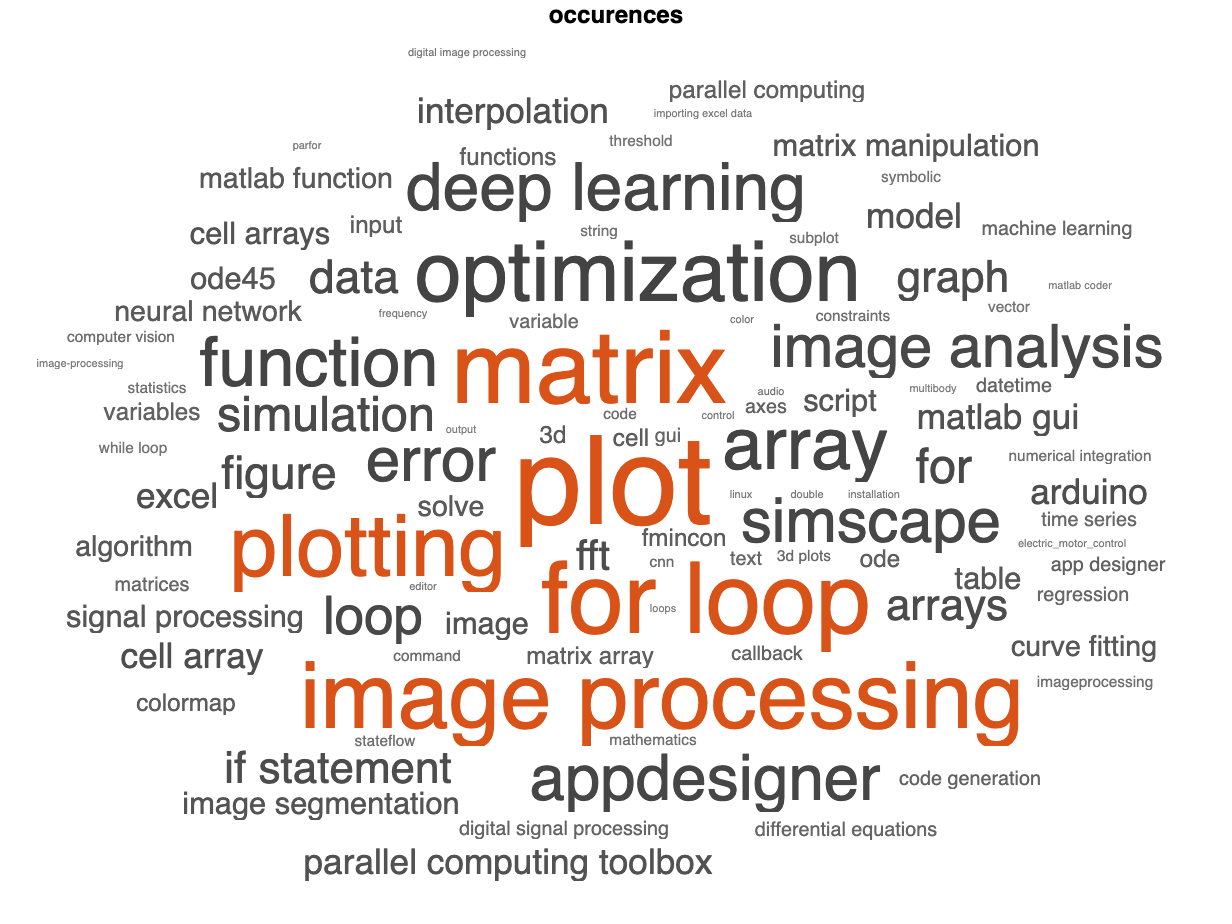

 figure
 wordcloud(TagTable,'uniqueTags','occurences')